% 实验4 样本矩和总体(中心)矩的关系
% 以正态分布总体为例
clf;
u   = 2.0;
sig = 2.0;
x_max = 2000

x_max = 2000

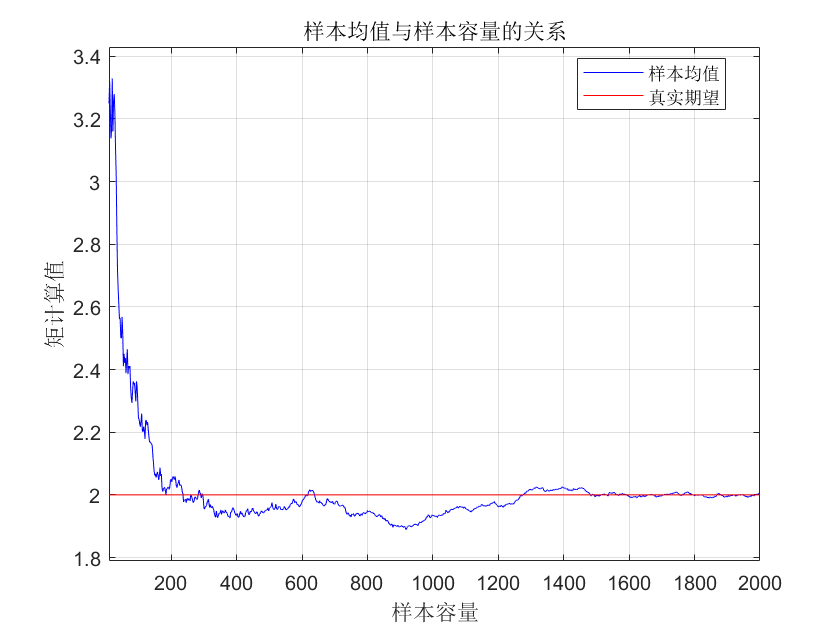

sample = normrnd(u, sig, 1, x_max);
xs = 10:2:x_max;
cpc = (x_max - 10)/2 + 1;
us = u * ones(1, cpc);
sigs = sig^2 * ones(1, cpc);
means = zeros(1, cpc);
stds = zeros(1, cpc);
cnt = 1;
for i = 10:2:x_max
    means(cnt) = mean(sample(1:i));
    stds(cnt) = std(sample(1:i))^2;
    cnt = cnt + 1;
end

% 期望的关系
figure(1)
plot(xs, means, "b");
hold on; axis on; grid on;
plot(xs, us, "r");
xlim([10, x_max]);
ylim([min(min(means)) - 0.1, max(max(means)) + 0.1]);
legend(["样本均值", "真实期望"], 'Location','best');
xlabel("样本容量");
ylabel("矩计算值");
title("样本均值与样本容量的关系");

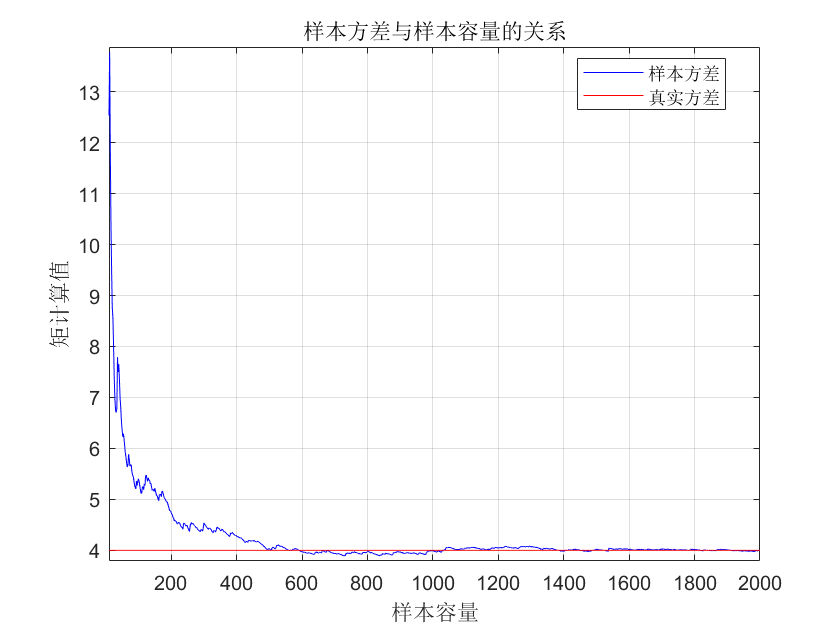


% 方差的关系
figure(2)
plot(xs, stds, "b");
hold on; axis on; grid on;
plot(xs, sigs, "r");
xlim([10, x_max]);
ylim([min(min(stds)) - 0.1, max(max(stds)) + 0.1]);
legend(["样本方差", "真实方差"], 'Location','best');
xlabel("样本容量");
ylabel("矩计算值");
title("样本方差与样本容量的关系");